# AAE 564 HW 1 

#### Author: Tomoki Koike

clear all; close all; clc;
fdir = 'C:\Users\Tomo\Desktop\studies\2020-Fall\AAE564\matlab_simulink\outputs\hw1';
set(groot, 'defaulttextinterpreter','latex');  
set(groot, 'defaultAxesTickLabelInterpreter','latex');  
set(groot, 'defaultLegendInterpreter','latex');

### Simulation 

% Simulate this system for given initial conditions 

% Initial conditions
IC1 = [0, -10, 10, 0, 0, 0];
IC2 = [0, 10, 10, 0, 0, 0];
IC3 = [0, -90, 90, 0, 0, 0];
IC4 = [0, -90.01, 90, 0, 0, 0];
IC5 = [0, 100, 100, 0, 0, 0];
IC6 = [0, 100.01, 100, 0, 0, 0];
IC7 = [0, 179.99, 0, 0, 0, 0];

% P1
m0 = 2;
m1 = 1;
m2 = 1;
l1 = 1;
l2 = 1;
g = 1;
u = 0;

t_span = linspace(0, 60, 2^10);  % time span
% opts = odeset('RelTol',1e-6,'AbsTol',1e-7);  % option for ode

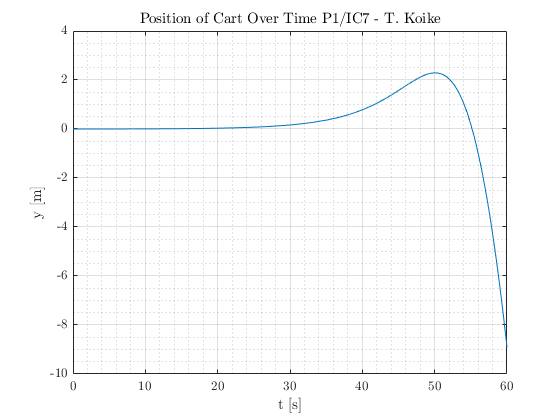

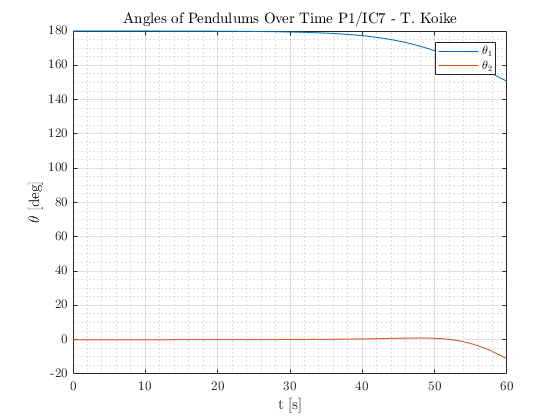

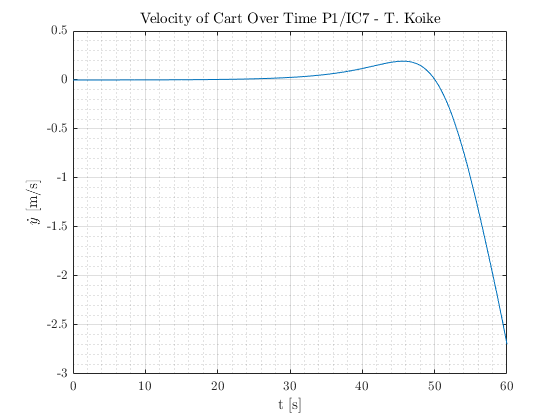

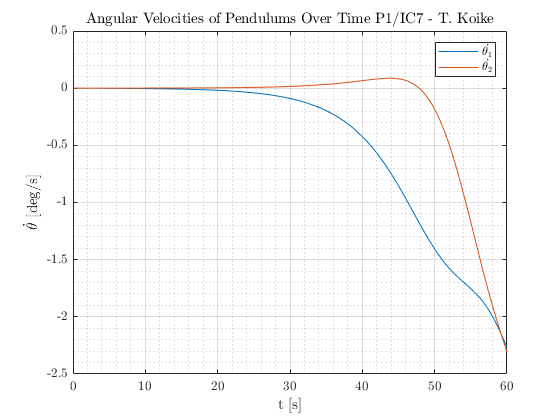

% P1 and IC1, IC2, IC3, IC7
IC = [IC1; IC2; IC3; IC7];
counter = 1;
for i = [1, 2, 3, 7]
    [t, q] = ode45(@(t, x) double_pendulum_system(t, x, m0, m1, m2, l1, l2, g, u), t_span, IC(counter,:));
    plot_simulation(t, q, fdir, "P1&IC"+num2str(i));
    counter = counter + 1;
end

% P4
m0 = 2;
m1 = 1;
m2 = 1;
l1 = 1;
l2 = 1;
g = 0.5;
u = 0;

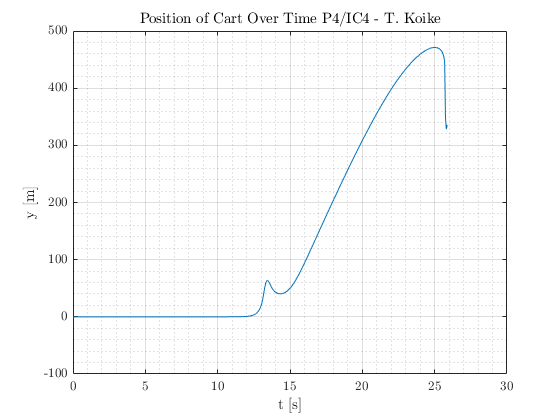

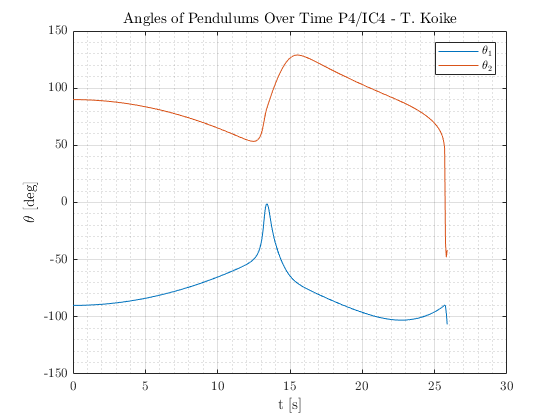

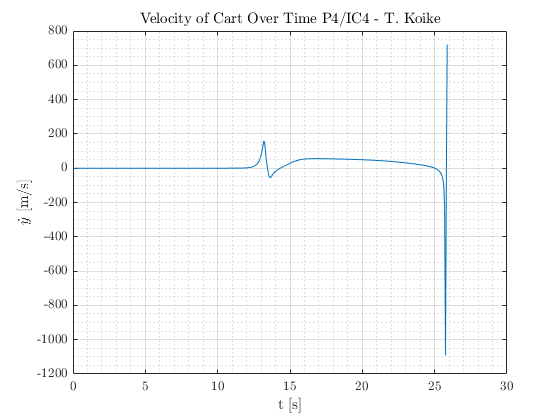

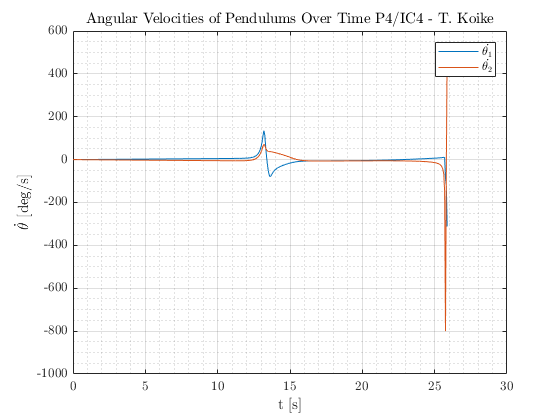

% P4 and IC1, IC2, IC3, IC4
IC = [IC1; IC2; IC3; IC4];
counter = 1;
for i = [1, 2, 3, 4]
    [t, q] = ode45(@(t, x) double_pendulum_system(t, x, m0, m1, m2, l1, l2, g, u), t_span, IC(counter,:));
    plot_simulation(t, q, fdir, "P4&IC"+num2str(i));
    counter = counter + 1;
end

### Functions

function dxdt = double_pendulum_system(t, x, m0, m1, m2, l1, l2, g, u)
    dxdt = zeros(6, 1);  % Preallocate the derivative vector 
    
    % Set the variables 
    y = x(1);
    theta1 = x(2);
    theta2 = x(3);
    y_dot = x(4);
    theta1_dot = x(5);
    theta2_dot = x(6);
    
    % Create matrices to simplify the calculations 
    M = [        m0 + m1 + m2, -m1*l1.*cosd(theta1), -m2*l2.*cosd(theta2);
         -m1*l1.*cosd(theta1),             m1*l1.^2,                    0;
         -m2*l2.*cosd(theta2),                    0,             m2*l2.^2 ];
    
    G = [(m1*l1.*sind(theta1).*theta1_dot.^2 + m2*l2.*sind(theta2).*theta2_dot.^2);...
        m1*l1*g.*sind(theta1); m2*l2*g.*sind(theta2)];
    
    W = [1; 0; 0];
    
    dxdt(1) = y_dot;
    dxdt(2) = theta1_dot;
    dxdt(3) = theta2_dot;
    dxdt(4:end) = M \ (W * u - G);    
end

function plot_simulation(t, q, file_dir, file_name_str)
    P_IC = split(file_name_str, "&");
    % Plot position of cart vs time
    fig1 = figure(1);
    plot(t, q(:, 1))
    title("Position of Cart Over Time "+P_IC(1)+"/"+P_IC(2)+ " - T. Koike")
    xlabel('t [s]')
    ylabel('y [m]')
    grid on; grid minor; box on;
    saveas(fig1, fullfile(file_dir, "y_"+file_name_str+".png"));
    
    % Plot the angles of pendulums vs time
    fig2 = figure(2);
    plot(t, q(:, 2))
    hold on 
    plot(t, q(:, 3))
    hold off
    title("Angles of Pendulums Over Time "+P_IC(1)+"/"+P_IC(2)+ " - T. Koike")
    xlabel('t [s]')
    ylabel('$\theta$ [deg]')
    legend('$\theta_1$', '$\theta_2$')
    grid on; grid minor; box on;
    saveas(fig2, fullfile(file_dir, "theta1&2_"+file_name_str+".png"));
    
    % Plot the velocity of cart vs time
    fig3 = figure(3);
    plot(t, q(:, 4))
    title("Velocity of Cart Over Time "+P_IC(1)+"/"+P_IC(2)+ " - T. Koike")
    xlabel('t [s]')
    ylabel('$\dot{y}$ [m/s]')
    grid on; grid minor; box on;
    saveas(fig3, fullfile(file_dir, "ydot_"+file_name_str+".png"));
    
    % Plot the angular velocities vs time
    fig4 = figure(4);
    plot(t, q(:, 5))
    hold on 
    plot(t, q(:, 6))
    hold off
    title("Angular Velocities of Pendulums Over Time "+P_IC(1)+"/"+P_IC(2)+ " - T. Koike")
    xlabel('t [s]')
    ylabel('$\dot{\theta}$ [deg/s]')
    legend('$\dot{\theta_1}$', '$\dot{\theta_2}$')
    grid on; grid minor; box on;
    saveas(fig4, fullfile(file_dir, "thetadot1&2_"+file_name_str+".png"));
end 